# Actividad 6.2 (Comparación de Algoritmos de Control)

Bruno Manuel Zamora Garcia A01798275

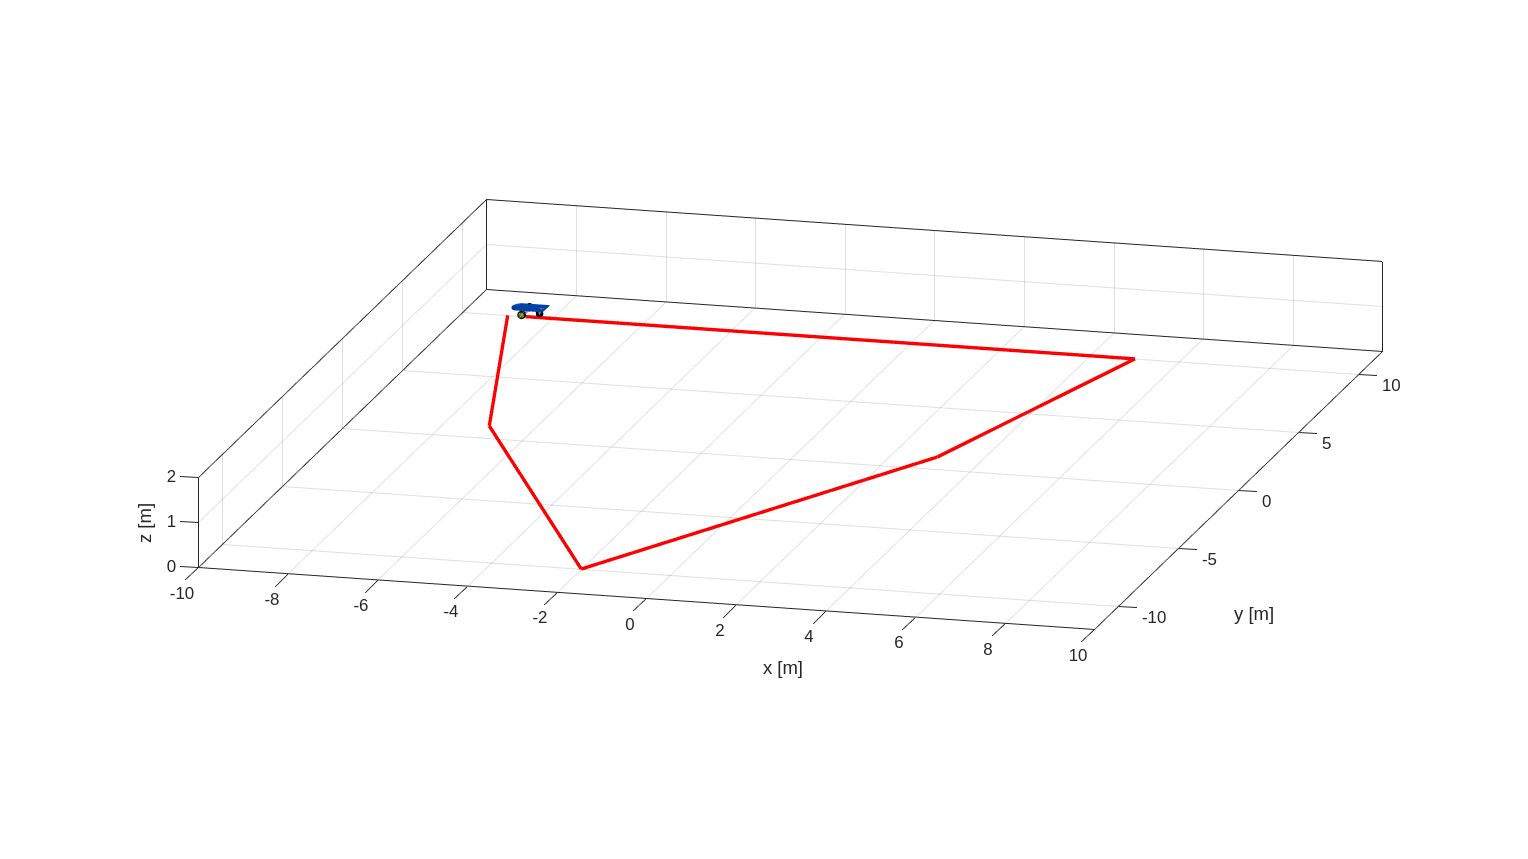


%% Sección 1: Lazo Abierto Preciso
% El robot recorre la trayectoria en “V” definida por:
% A(-9,10) → B(-7,1) → C(-2,-10) → D(3,1) → E(5,10) → A(-9,10)

clear; close all; clc                       % Limpiar entorno y ventana de comandos

% 1) Definición de puntos (incluye regreso a A)
pts = [ -9  10;  % A
        -7   1;  % B
        -2 -10;  % C
         3   1;  % D
         5  10;  % E
        -9  10]; % Vuelta a A       

% 2) Parámetros de simulación
ts      = 0.1;    % Paso de muestreo [s]
v_const = 1;      % Velocidad lineal constante [m/s]
w_const = 1;      % Velocidad angular constante [rad/s]

% 3) Cálculo de distancias y orientaciones absolutas
dp        = diff(pts);                         % Desplazamientos entre puntos
distances = hypot(dp(:,1), dp(:,2));           % Longitudes exactas de cada tramo
headings  = atan2(dp(:,2), dp(:,1));           % Ángulos absolutos de cada tramo

% 4) Cálculo de giros necesarios (Δφ) partiendo de φ0=0
phi0 = 0;                                      % Orientación inicial
dphi = [ wrapToPi(headings(1)-phi0);           % Primer giro
         wrapToPi(diff(headings)) ];           % Giros siguientes

% 5) Convertir Δφ y distancias a número de muestras
n_turn = ceil(abs(dphi)  / w_const / ts);      % Muestras para cada giro
n_line = ceil(distances / v_const / ts);       % Muestras para cada avance

% 6) Definir perfiles constantes que cumplan Δφ y distancia exacta
w_prof = dphi ./ (n_turn * ts);                % ω para integrar Δφ exacto
u_prof = distances ./ (n_line * ts);           % u para recorrer distancia exacta

% 7) Ensamblar vectores de comandos u y w
N = sum(n_turn) + sum(n_line);                 % Total de muestras
t = (0:N-1)*ts;                                % Vector de tiempo
u = zeros(1,N); w = zeros(1,N);                % Preasignación
idx = 1;                                       % Índice inicial
for i = 1:length(dphi)
    w(idx:idx+n_turn(i)-1) = w_prof(i);        % Asignar velocidad angular
    idx = idx + n_turn(i);
    u(idx:idx+n_line(i)-1) = u_prof(i);        % Asignar velocidad lineal
    idx = idx + n_line(i);
end

% 8) Simulación cinemática (Euler)
x1  = zeros(1,N+1);  y1  = zeros(1,N+1);  phi = zeros(1,N+1);
x1(1) = -9;  y1(1) = 10;  phi(1) = phi0;
for k = 1:N
    phi(k+1) = phi(k) + w(k)*ts;              % Integración de orientación
    x1(k+1)  = x1(k) + u(k)*cos(phi(k+1))*ts; % Integración de x
    y1(k+1)  = y1(k) + u(k)*sin(phi(k+1))*ts; % Integración de y
end
hx = x1;  hy = y1;                             % Punto de control = pose

% 9) Animación 3D
scene = figure;
set(scene,'Color','white','Position',get(0,'ScreenSize'));
camlight headlight; axis equal; grid on; box on;
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]');
view([15 15]); axis([-10 10 -12 12 0 2]);
scale = 4; MobileRobot_5;
H1 = MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2 = plot3(hx(1),hy(1),0,'r','LineWidth',2);
for k = 1:5:N
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2 = plot3(hx(1:k),hy(1:k),zeros(1,k),'r','LineWidth',2);
    pause(ts);
end

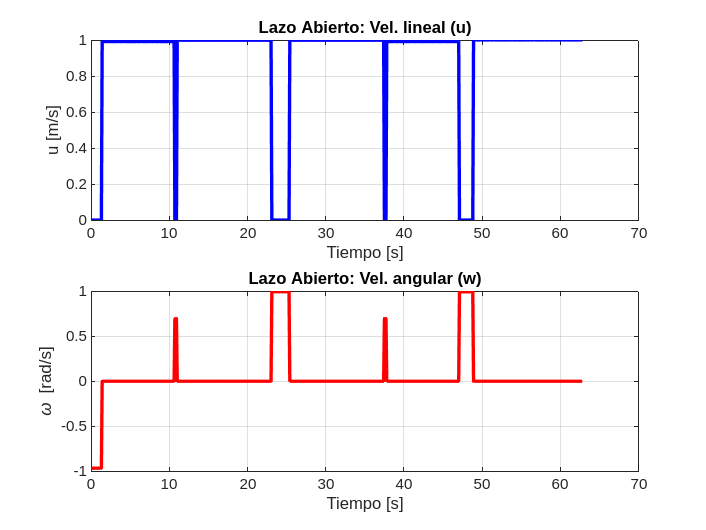


% 10) Gráficas de entradas
figure;
subplot(2,1,1)
plot(t,u,'b','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('u [m/s]'), title('Lazo Abierto: Vel. lineal (u)')
subplot(2,1,2)
plot(t,w,'r','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('\omega [rad/s]'), title('Lazo Abierto: Vel. angular (w)')

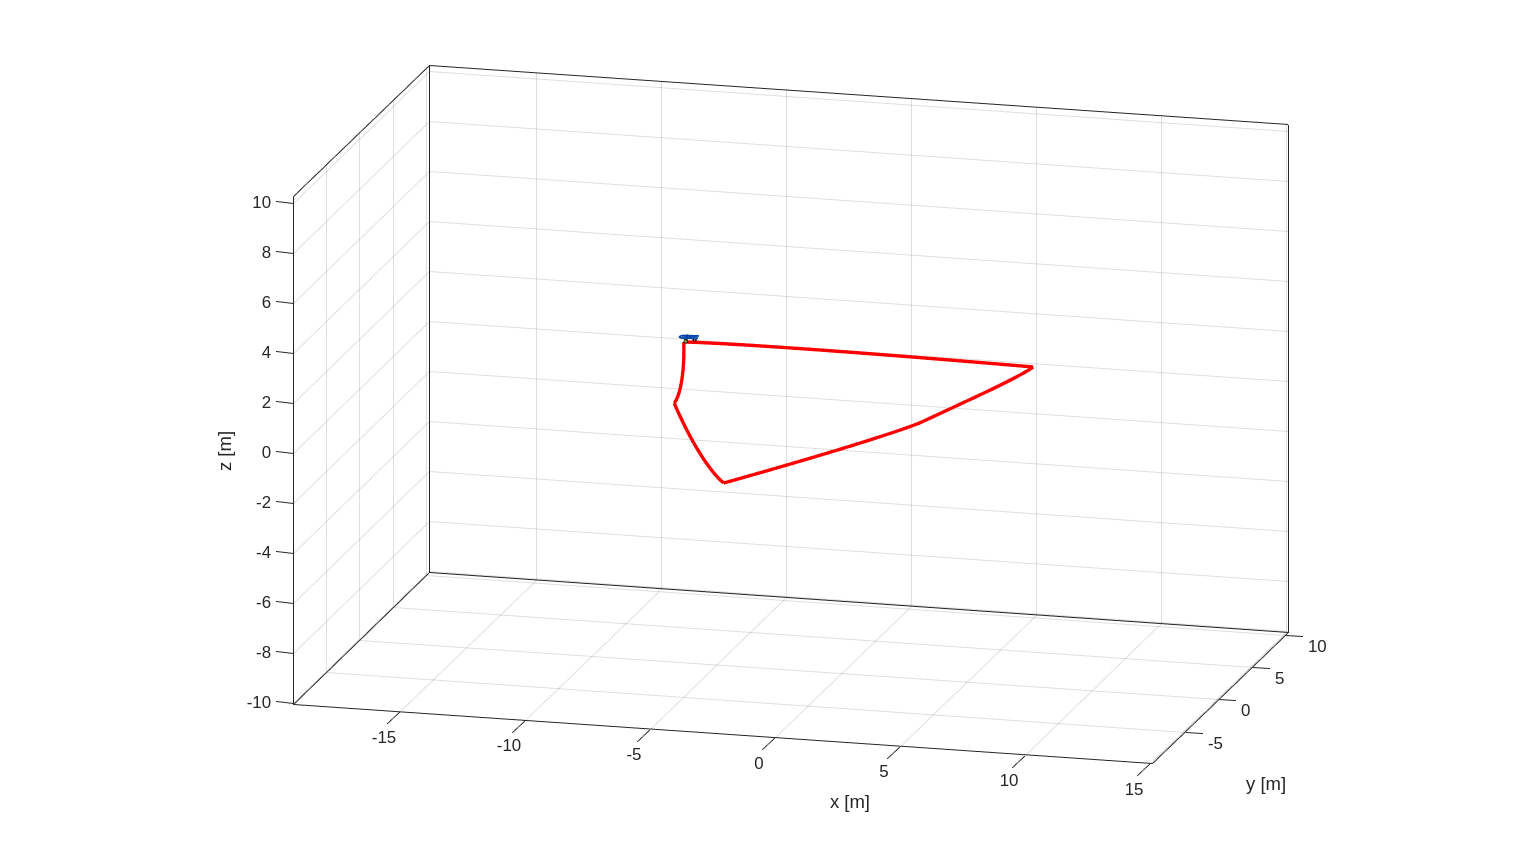




%% Sección 2: Lazo cerrado (Control de Posición)
clc  % Limpia solo la ventana de comandos para no borrar las gráficas

% 1) Definición de waypoints A→B→C→D→E→A
pts = [ -9  10;  % A
        -7   1;  % B
        -2 -10;  % C
         3   1;  % D
         5  10;  % E
        -9  10]; % Regreso a A

% 2) Parámetros de simulación
ts       = 0.05;  
tf       = 100;   
t        = 0:ts:tf;
maxSteps = length(t);

% 3) Inicializar estados en A
x1  = zeros(1,maxSteps+1);  y1  = zeros(1,maxSteps+1);
phi = zeros(1,maxSteps+1);
x1(1) = -9;           y1(1)= 10;  phi(1)= 0;

% 4) Ganancias y umbrales de control
K_rho    = 0.5;   K_alpha = 1.0;
rho_th   = 0.1;   alpha_th= 0.05;

% 5) Vectores de acción y error
u   = zeros(1,maxSteps);  w   = zeros(1,maxSteps);
err = zeros(1,maxSteps);

currentWP = 2;  % Primer waypoint: B
step      = 1;  % Índice de tiempo

% 6) Bucle de control “girar → avanzar”
while currentWP <= size(pts,1) && step <= maxSteps
    dx  = pts(currentWP,1) - x1(step);
    dy  = pts(currentWP,2) - y1(step);
    rho = hypot(dx,dy);  err(step) = rho;
    if rho < rho_th
        currentWP = currentWP + 1; continue;
    end
    theta_d = atan2(dy,dx);
    alpha   = wrapToPi(theta_d - phi(step));
    if abs(alpha) > alpha_th
        u(step) = 0; 
        w(step) = K_alpha * alpha;
    else
        u(step) = K_rho * rho;
        w(step) = 0;
    end
    % Cinemática diferencial
    x1(step+1)  = x1(step)  + u(step)*cos(phi(step))*ts;
    y1(step+1)  = y1(step)  + u(step)*sin(phi(step))*ts;
    phi(step+1) = phi(step) + w(step)*ts;
    step = step + 1;
end

% 7) Recortar vectores a tamaño real
x1  = x1(1:step);  y1  = y1(1:step);  phi = phi(1:step);
u   = u(1:step-1); w   = w(1:step-1); err = err(1:step-1);
t_sim = (0:length(u)-1)*ts;

% 8) Animación 3D
scene = figure; set(scene,'Color','white','Position',get(0,'ScreenSize'));
camlight headlight; axis equal; grid on; box on;
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]'); view([15 15]);
scale = 4; MobileRobot_5;
H1 = MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2 = plot3(x1(1),y1(1),0,'r-','LineWidth',2);
for k = 1:5:length(x1)
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2 = plot3(x1(1:k),y1(1:k),zeros(1,k),'r-','LineWidth',2);
    pause(ts);
end

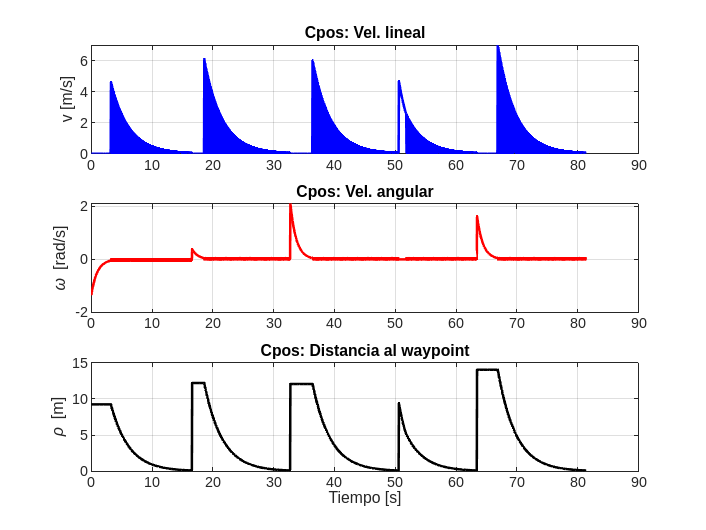


% 9) Gráficas de velocidad lineal, angular y error
figure;
subplot(3,1,1)
plot(t_sim,u,'b','LineWidth',1.5), grid on
ylabel('v [m/s]'), title('Cpos: Vel. lineal')
subplot(3,1,2)
plot(t_sim,w,'r','LineWidth',1.5), grid on
ylabel('\omega [rad/s]'), title('Cpos: Vel. angular')
subplot(3,1,3)
plot(t_sim,err,'k','LineWidth',1.5), grid on
xlabel('Tiempo [s]'), ylabel('\rho [m]'), title('Cpos: Distancia al waypoint')

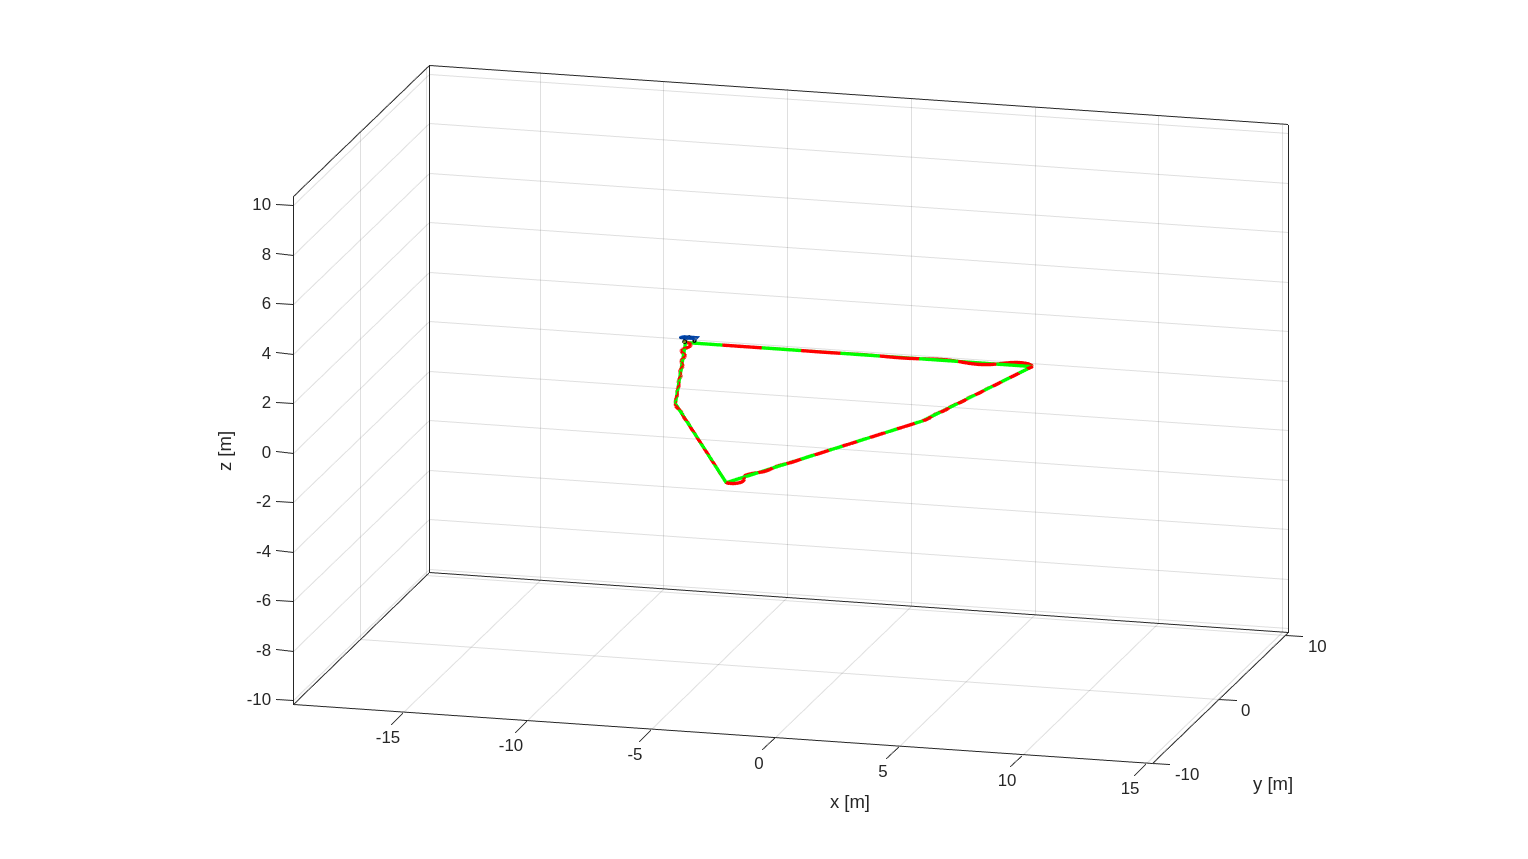


%% Sección 3: Lazo cerrado (Control de Trayectoria)
clc  % Limpiar solo ventana de comandos

% 1) Parámetros de trayectoria “V”
ts    = 0.1;     % Paso de simulación [s]
v_des = 0.5;     % Vel. deseada [m/s]
pts   = [ -9 10; -7 1; -2 -10; 3 1; 5 10; -9 10 ];  % Cierra el lazo

% 2) Construcción por interpolación lineal
distances = hypot(diff(pts(:,1)), diff(pts(:,2)))';
durations = distances / v_des;
samples   = round(durations/ts);
N         = sum(samples);
t_vec     = (0:N-1)*ts;

hxd  = zeros(1,N); hyd  = zeros(1,N);
hxdp = zeros(1,N); hydp = zeros(1,N);
idx = 1;
for i = 1:length(samples)
    n   = samples(i);
    x0  = pts(i,1);  y0  = pts(i,2);
    x1p = pts(i+1,1); y1p = pts(i+1,2);
    % 2.1) Posición deseada
    hxd(idx:idx+n-1)  = linspace(x0,x1p,n);
    hyd(idx:idx+n-1)  = linspace(y0,y1p,n);
    % 2.2) Velocidad deseada constante
    hxdp(idx:idx+n-1) = (x1p-x0)/durations(i);
    hydp(idx:idx+n-1) = (y1p-y0)/durations(i);
    idx = idx + n;
end

% 3) Estados iniciales
x1  = zeros(1,N+1); y1  = zeros(1,N+1); phi = zeros(1,N+1);
x1(1)=-9;    y1(1)=10;

% 4) Ganancias y preasignación
K = diag([10,2]);
v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);

% 5) Bucle de control
for k = 1:N
    he    = [hxd(k)-x1(k); hyd(k)-y1(k)];
    Error(k) = norm(he);
    J     = [cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];
    qp    = pinv(J)*([hxdp(k); hydp(k)] + K*he);
    v(k)  = qp(1);  w(k) = qp(2);
    phi(k+1) = phi(k) + w(k)*ts;
    x1(k+1)  = x1(k) + v(k)*cos(phi(k))*ts;
    y1(k+1)  = y1(k) + v(k)*sin(phi(k))*ts;
end
hx = x1; hy = y1;

% 6) Animación 3D
scene = figure; set(scene,'Color','white','Position',get(0,'ScreenSize'));
camlight headlight; axis equal; grid on; box on;
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]'); view([15 15]);
MobileRobot_5;
H1 = MobilePlot_4(x1(1),y1(1),phi(1),4); hold on;
H2 = plot3(hx(1),hy(1),0,'r','LineWidth',2);
H3 = plot3(hxd,hyd,zeros(1,N),'g','LineWidth',2);
for k = 1:5:N
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k),y1(k),phi(k),4);
    H2 = plot3(hx(1:k),hy(1:k),zeros(1,k),'r','LineWidth',2);
    pause(ts);
end

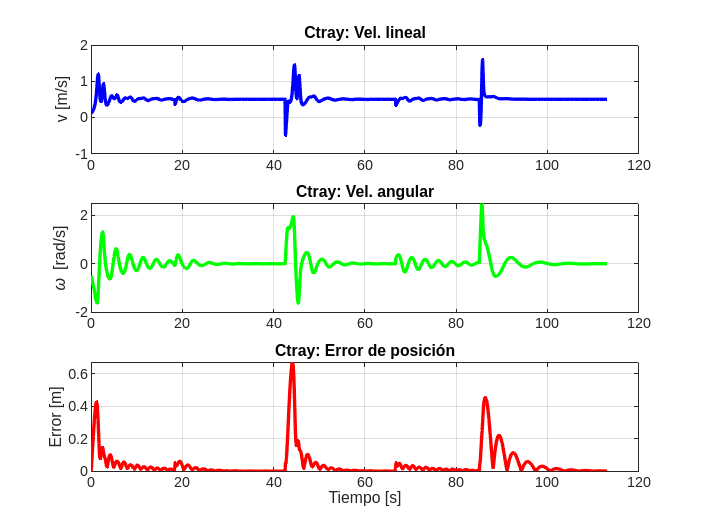


% 7) Gráficas de velocidad y error
figure;
subplot(3,1,1)
plot(t_vec,v,'b','LineWidth',2), grid on
ylabel('v [m/s]'), title('Ctray: Vel. lineal')
subplot(3,1,2)
plot(t_vec,w,'g','LineWidth',2), grid on
ylabel('\omega [rad/s]'), title('Ctray: Vel. angular')
subplot(3,1,3)
plot(t_vec,Error,'r','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('Error [m]'), title('Ctray: Error de posición')

En este proyecto comparé tres esquemas de control para que el robot recorriera la “V” A→B→C→D→E: el lazo abierto me permitió prototipar muy rápido con la cinemática básica, pero el error se acumula y no tolera perturbaciones; el control de posición corrigió puntualmente cada vértice (ρ < 0.1 m) y es fácil de sintonizar, aunque deja un trazo escalonado por el “para–gira–avanza”; y el control de trayectoria fue el más preciso y suave, reproduciendo casi al milímetro la ruta deseada, aunque exige más cómputo (pinv(J), derivadas, medición de φ) y ajuste de una matriz de ganancias. Por eso, usaré lazo abierto para demos simples sin perturbaciones, control de posición cuando necesite robustez y facilidad de ajuste, y control de trayectoria cuando busque máxima exactitud y continuidad en el seguimiento.